## Experimento 3 - MP3 Player (Parte 3)

#### Bruno Hashimoto - 10715628

#### Guilherme Fernandes - 10297272

clear;
clc;

addpath(".", "data/", "functions/");
load('data/Analise_Sintese32.mat');

### **3.a) **Gráfico do módulo da resposta em frequência dos 32 filtros.

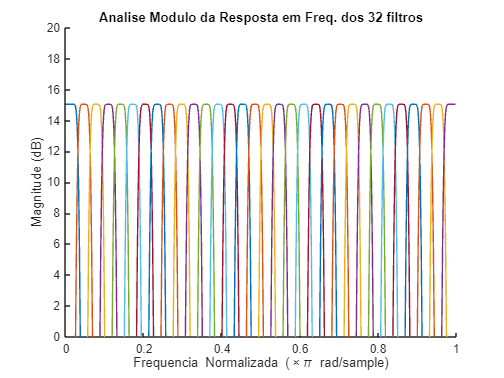

n_canais = 32; % numero de canais
H = zeros(n_canais, 512); % inicializacao dos filtros

figure;
for i=1:n_canais
    [H(i, :), w] = freqz(PQMF32_Hfilters(i,:), 1);

    hold on;
    plot(w/pi, 20*log10(abs(H(i,:))));
end

title('Analise Modulo da Resposta em Freq. dos 32 filtros');
xlabel('Frequencia Normalizada (\times\pi rad/sample)');
ylabel('Magnitude (dB)');
ylim([0 20]);

É possível observar no gráfico acima que o ganho dos 32 filtros é de 15dB e que para uma certa banda ocorre superposição (apenas!) com as bandas adjacentes. A dupla filtragem que será realizada portanto, já compensa o efeito da dizimação de 32 o que faz desnecessária a multiplicação da super amostragem pelo fator de amostragem.

### **3.b) Reconstrução do Chirp com banco de filtros pseudo-QMF com 32 Canais**

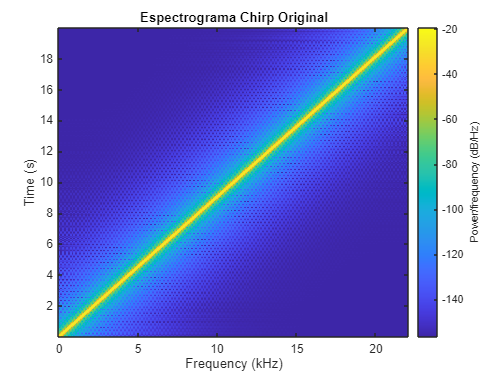

t_inicial = 0;
t_final = 20;
f_final = 22050; % Hz
f_a = 44100; % frequencia de amostragem [Hz]

x = gera_chirp(t_inicial, t_final, f_final, f_a);

figure;
spectrogram(x, hanning(512), 256, 1024, f_a);
title('Espectrograma Chirp Original');

Estendendo o processo de análise e síntese do exercício anterior agora obtém-se para os 32 canais o seguinte resultado.

y = [];
for i=1:n_canais
    % analise
    vi = filter(PQMF32_Hfilters(i,:), 1, x);
    vi = sub_amostragem(vi, n_canais);
    % sintese
    yi = sobre_amostragem(vi, n_canais);
    y(i,:) = filter(PQMF32_Gfilters(i,:), 1, yi);
end

Somando as componentes de cada canal.

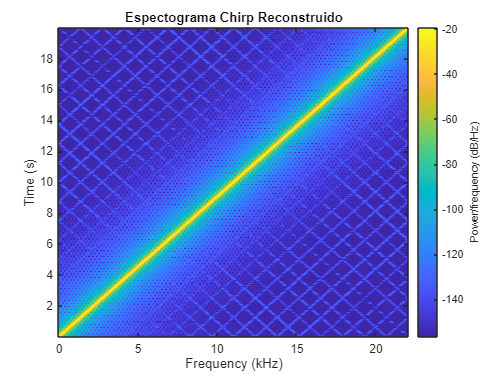

% removendo o atraso gerado pelos filtros
[~, filter_size] = size(PQMF32_Hfilters);
filter_order = filter_size-1;

y_sum = sum(y, 1);
y_sem_atraso = y_sum(filter_order+1:end);

figure;
spectrogram(y_sem_atraso, hanning(512), 256, 1024, f_a);
title('Espectograma Chirp Reconstruido');

Erro absoluto

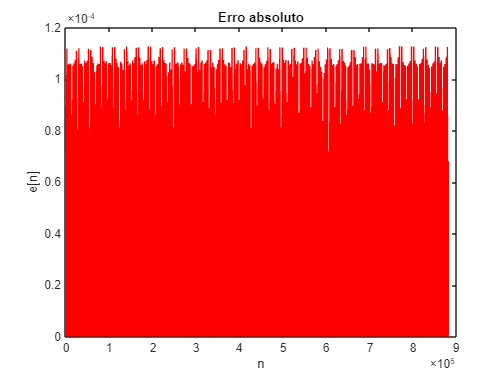

n_y = length(y_sem_atraso);
abs_error = abs(x(1:n_y) - y_sem_atraso);

figure;
plot(0:n_y-1, abs_error, 'r');
xlabel('n');
ylabel('e[n]');
title('Erro absoluto');

### **3.c) SNR do sinal reconstruído**

% funcao SNR fornecida pelos professores
% disponivel na pasta 'functions'
SNR_PQMF = snr(x(1:n_y), y_sem_atraso, 0)

SNR_PQMF = 84.3497

### 3.d) Violino

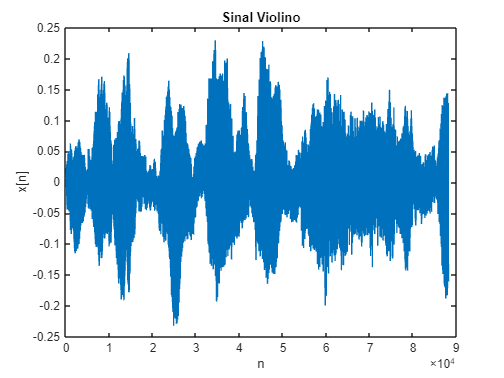


[x_violino, fa] = audioread('data/violino.wav');
x_violino = x_violino';
n_amostras = length(x_violino);

figure;
plot(0:n_amostras-1, x_violino);
ylabel('x[n]');
xlabel('n');
title('Sinal Violino');

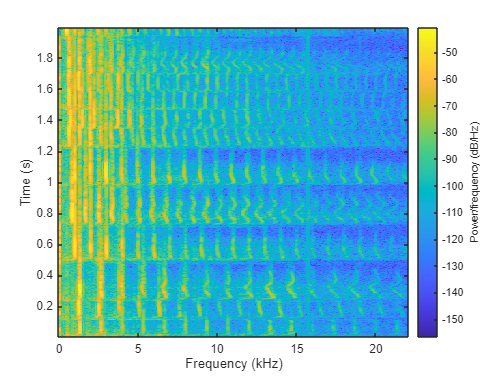

figure;
spectrogram(x_violino, hanning(512), 256, 1024, fa);

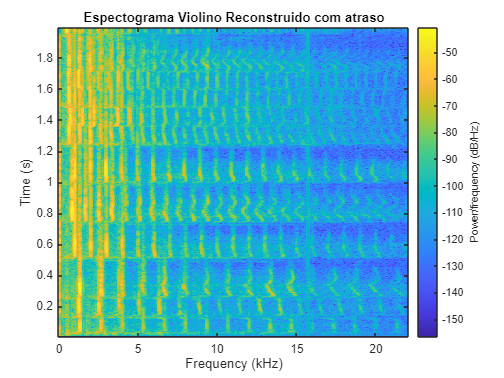

y = [];

for i=1:n_canais
    % analise
    vi = filter(PQMF32_Hfilters(i,:), 1, x_violino);
    vi = sub_amostragem(vi, n_canais);
    % sintese
    yi = sobre_amostragem(vi, n_canais);
    y(i,:) = filter(PQMF32_Gfilters(i,:), 1, yi);
end

y_sum = sum(y, 1);
y_sem_atraso = y_sum(filter_order+1:end);

figure;
spectrogram(y_sum, hanning(512), 256, 1024, fa);
title('Espectograma Violino Reconstruido com atraso');

Gráficos sinais de saída do filtros de síntese dos canais 0, 5 e 10

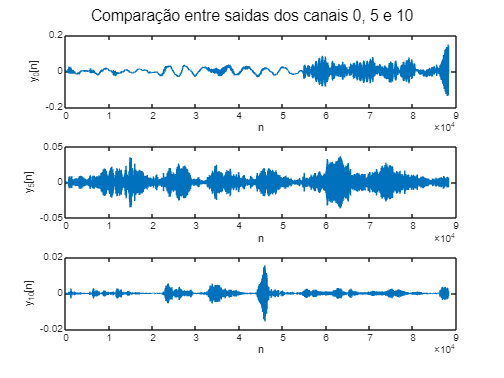

figure;
subplot(3,1,1);
plot(y(1,:));
xlabel('n');
ylabel('y_0[n]');

subplot(3,1,2);
plot(y(6,:));
xlabel('n');
ylabel('y_5[n]');

subplot(3,1,3);
plot(y(11,:));
xlabel('n');
ylabel('y_{10}[n]');

sgtitle('Comparação entre saidas dos canais 0, 5 e 10');

Uma análise das saidas dos canais 0, 5 e 10, indicam que cada canal realiza uma filtragem diferente no sinal, assim como observa-do na resposta em frequência de todos os filtros no começo deste documento.

Cálculo do erro absoluto e SNR

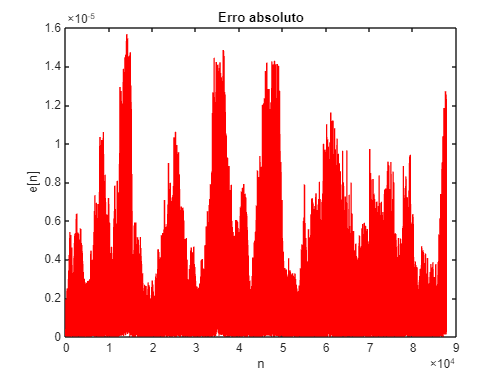

n_amostras_sem_atraso = length(y_sem_atraso);
abs_error_violino = abs(x_violino(1:n_amostras_sem_atraso) - y_sem_atraso);

figure;
plot(0:n_amostras_sem_atraso-1, abs_error_violino, 'r');
xlabel('n');
ylabel('e[n]');
title('Erro absoluto');

SNR_PQMF_violino = snr(x_violino(1:n_amostras_sem_atraso), y_sem_atraso, 0)

SNR_PQMF_violino = 84.2421